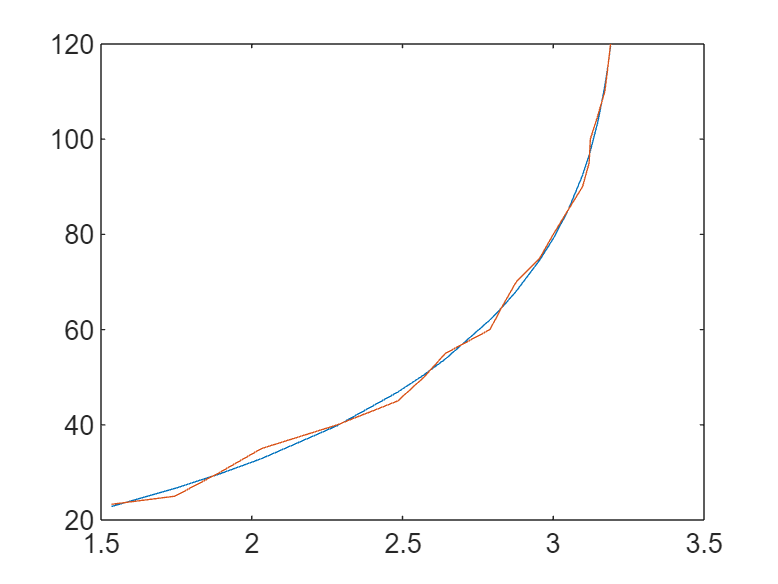

Temps = [23.3 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100 105 110 115 120];
v1 = [1.535 1.745 1.894 2.032 2.284 2.484 2.571 2.642 2.790 2.832 2.877 2.955 3.000 3.048 3.097 3.119 3.123 3.148 3.171 3.181 3.190];
v2 = [1.577 1.755 1.842 2.003 2.223 2.403 2.500 2.571 2.723 2.771 2.826 2.903 2.952 3.000 3.055 3.084 3.097 3.123 3.148 3.161 3.171];
v3 = 1.824;

R_T = 9.76e3;
R_S1 = (R_T*(3.3-v1))./v1;
R_S2 = (R_T*(3.3-v2))./v2;
R_S3 = (R_T*(3.3-v3))./v3;

p1 = polyfit(log(R_S1/R_T), 1./Temps, 4);
y1 = polyval(p1, log(R_S1/R_T));
plot(v1, y1.^(-1));
hold on
plot(v1, Temps);
hold off

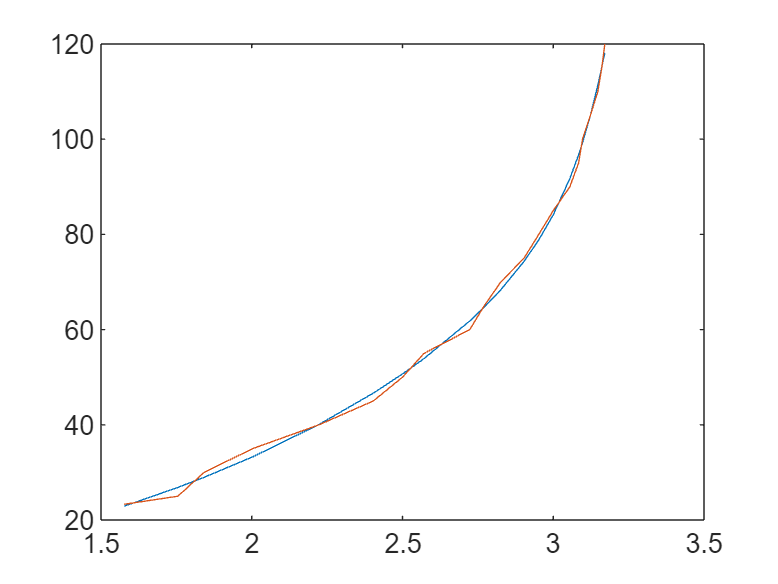


p2 = polyfit(log(R_S2/R_T), 1./Temps, 4);
y2 = polyval(p2, log(R_S2/R_T));
plot(v2, y2.^(-1));
hold on
plot(v2, Temps);
hold off


y3 = polyval(p2, log(R_S3/R_T));
Ttest = y3^(-1)

Ttest = 28.5163

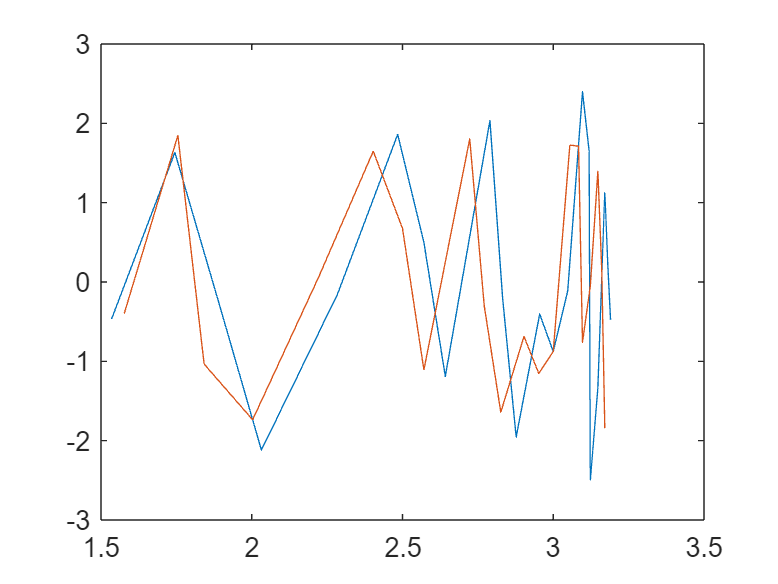


res1 = y1.^(-1)-Temps;
res2 = y2.^(-1)-Temps;
plot(v1, res1)
hold on
plot(v2, res2)
hold off